# PRÁCTICA INTERPOLACIÓN NUMÉRICA (LAGRANGE)

**PRIMER SOPORTE: S1={x0=0, x1=2}**

1) Programamos la expresión de los polinomios de base de Lagrange:

%Limpiamos las variables del entorno
clear
%Declaración de variables simbólicas que se utilizarán
syms x L xk xj fi a b
syms x1 x2

%Programamos la expresión simbólica de los polinomios de base de Lagrange:
v=sym([x1,x2])

$$v = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

n=length(v)

n = 2

L=sym(linspace(1,1,n))

$$L = \left(\begin{array}{cc} 1 & 1 \end{array}\right)$$

for i=1:n %For que crea los Li
    for j=1:n %For del productorio de cada Li
        if (i~=j)
            Li=(x-xj)/(xk-xj)
            prod=subs(Li,{xk,xj},{v(i),v(j)})
            L(i)=L(i)*prod   
        end
    end
end

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{2}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{cc} \frac{x-x_{2}}{x_{1}-x_{2}} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{cc} \frac{x-x_{2}}{x_{1}-x_{2}} & -\frac{x-x_{1}}{x_{1}-x_{2}} \end{array}\right)$$

Sustituimos los valores en la expresión de los polinomios de base de Lagrange:

v1 = sym([0,2])

$$v1 = \left(\begin{array}{cc} 0 & 2 \end{array}\right)$$

n = length(v1)

n = 2


LE = sym(zeros(1,n))

$$LE = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


c1 = 1:n

c1 =      1     2


for i=1:n
    prod1 = 1
    k1 = c1
    k1(i) = [] %Para asegurarnos de que i<>j
    for j1=k1
        prod1 = prod1*(x-v1(j1))/(v1(i)-v1(j1))
    end
    LE(i) = prod1
end

prod1 = 1

k1 =      1     2


k1 = 2

$$prod1 = 1-\frac{x}{2}$$

$$LE = \left(\begin{array}{cc} 1-\frac{x}{2} & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2


k1 = 1

$$prod1 = \frac{x}{2}$$

$$LE = \left(\begin{array}{cc} 1-\frac{x}{2} & \frac{x}{2} \end{array}\right)$$

Representamos gráficamente estos polinomios de base de Lagrange:

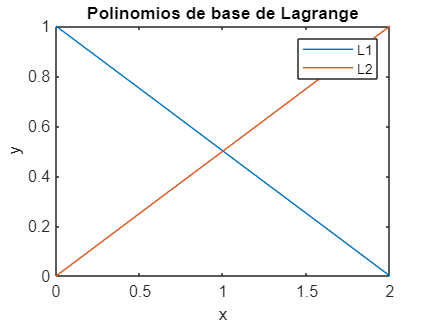

fplot(LE,[0 2])
 
% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomios de base de Lagrange')
legend("L1","L2")

2) Programamos la expresión del polinomio interpolador de Lagrange:

syms f1 f2
fun=[f1,f2]

$$fun = \left(\begin{array}{cc} f_{1} & f_{2} \end{array}\right)$$

 
syms L1 L2 
l=sym([L1,L2])

$$l = \left(\begin{array}{cc} L_{1} & L_{2} \end{array}\right)$$

pn=0

pn = 0

for i=1:n
    pI=fi*Li
    val=subs(pI,{fi,Li},{fun(i),l(i)})
    pn=pn+val
end

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{1}\,f_{1}$$

$$pn = L_{1}\,f_{1}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{2}\,f_{2}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}$$

Sustituimos los valores para obtener el polinomio interpolador de Lagrange:

%Definimos nuestra función (la usaremos en todos los soportes)
f(x) = exp(-x)+cos(4*x/pi)

$$f(x) = {\mathrm{e}}^{-x}+\cos\left(\frac{4\,x}{\pi }\right)$$


sum = 0

sum = 0

for i=1:n
    sum = sum + LE(i)*f(v1(i))
end

$$sum = 2-x$$

$$sum = \frac{x\,\left({\mathrm{e}}^{-2}+\cos\left(\frac{8}{\pi }\right)\right)}{2}-x+2$$


digits(4) 
numSum = vpa(sum) %Para que la solución aparezca más visible

$$numSum = 2.0-1.346\,x$$

p1 = expand(numSum)

$$p1 = 2.0-1.346\,x$$

Representamos gráficamente el polinomio interpolador de Lagrange junto con la función original:

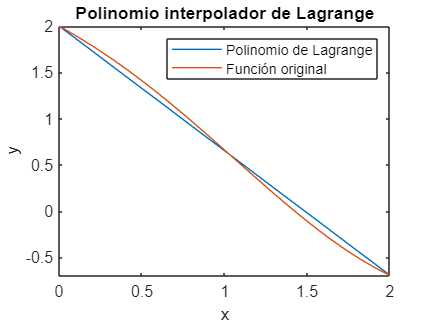

fplot(numSum,[0 2])
hold on
fplot(f(x),[0 2])
hold off

% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomio interpolador de Lagrange')
legend("Polinomio de Lagrange","Función original")

**SEGUNDO SOPORTE: S2={x0=0, x1=1 ,x2=2}**

Calculamos el nuevo soporte añadiendo una variable más:

%Calculemos la distancia (constante) que habrá entre los nuevos puntos del
%soporte
hsym = sym((b-a)/n)

$$hsym = \frac{b}{2}-\frac{a}{2}$$

%Sustituimos los valores de a, b y n para nuestro ejemplo:
h = subs(hsym,[b,a,n],[2,0,2])

$$h = 1$$


%Por tanto, el nuevo soporte será el siguiente:
v2=sym([0,1,2])

$$v2 = \left(\begin{array}{ccc} 0 & 1 & 2 \end{array}\right)$$

1) Programamos la expresión de los polinomios de base de Lagrange:

%Limpiamos las variables del entorno
clear
%Declaración de variables simbólicas que se utilizarán
syms x L xk xj fi a b
syms x1 x2 x3

%Programamos la expresión simbólica de los polinomios de base de Lagrange:
v=sym([x1,x2,x3])

$$v = \left(\begin{array}{ccc} x_{1} & x_{2} & x_{3} \end{array}\right)$$

n=length(v)

n = 3

L=sym(linspace(1,1,n))

$$L = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$

for i=1:n %For que crea los Li
    for j=1:n %For del productorio de cada Li
        if (i~=j)
            Li=(x-xj)/(xk-xj)
            prod=subs(Li,{xk,xj},{v(i),v(j)})
            L(i)=L(i)*prod   
        end
    end
end

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{2}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{ccc} \frac{x-x_{2}}{x_{1}-x_{2}} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & -\frac{x-x_{1}}{x_{1}-x_{2}} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & -\frac{x-x_{1}}{x_{1}-x_{3}} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{ccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)} \end{array}\right)$$

Sustituimos los valores en la expresión de los polinomios de base de Lagrange:

v2=sym([0,1,2])

$$v2 = \left(\begin{array}{ccc} 0 & 1 & 2 \end{array}\right)$$

n = length(v2)

n = 3


LE = sym(zeros(1,n))

$$LE = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$


c1 = 1:n

c1 =      1     2     3


for i=1:n
    prod1 = 1
    k1 = c1
    k1(i) = []
    for j1=k1
        prod1 = prod1*(x-v2(j1))/(v2(i)-v2(j1))
    end
    LE(i) = prod1
end

prod1 = 1

k1 =      1     2     3


k1 =      2     3


$$prod1 = 1-x$$

$$prod1 = \frac{\left(x-1\right)\,\left(x-2\right)}{2}$$

$$LE = \left(\begin{array}{ccc} \frac{\left(x-1\right)\,\left(x-2\right)}{2} & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3


k1 =      1     3


$$prod1 = x$$

$$prod1 = -x\,\left(x-2\right)$$

$$LE = \left(\begin{array}{ccc} \frac{\left(x-1\right)\,\left(x-2\right)}{2} & -x\,\left(x-2\right) & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3


k1 =      1     2


$$prod1 = \frac{x}{2}$$

$$prod1 = \frac{x\,\left(x-1\right)}{2}$$

$$LE = \left(\begin{array}{ccc} \frac{\left(x-1\right)\,\left(x-2\right)}{2} & -x\,\left(x-2\right) & \frac{x\,\left(x-1\right)}{2} \end{array}\right)$$

Representamos gráficamente estos polinomios de base de Lagrange:

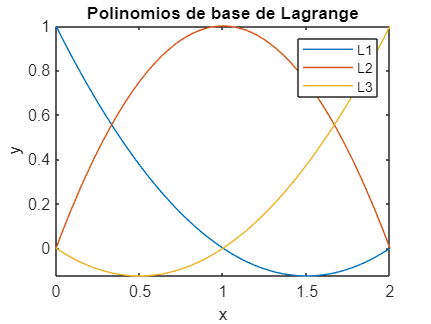

fplot(LE,[0 2])
 
% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomios de base de Lagrange')
legend("L1","L2","L3")

2) Programamos la expresión del polinomio interpolador de Lagrange:

syms f1 f2 f3
fun=[f1,f2,f3]

$$fun = \left(\begin{array}{ccc} f_{1} & f_{2} & f_{3} \end{array}\right)$$


syms L1 L2 L3
l=sym([L1,L2,L3])

$$l = \left(\begin{array}{ccc} L_{1} & L_{2} & L_{3} \end{array}\right)$$

pn=0

pn = 0

for i=1:n
    pI=fi*Li
    val=subs(pI,{fi,Li},{fun(i),l(i)})
    pn=pn+val
end

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{1}\,f_{1}$$

$$pn = L_{1}\,f_{1}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{2}\,f_{2}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{3}\,f_{3}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}$$

Sustituimos los valores para obtener el polinomio interpolador de Lagrange:

%Definimos nuestra función (la usaremos en todos los soportes)
f(x) = exp(-x)+cos(4*x/pi)

$$f(x) = {\mathrm{e}}^{-x}+\cos\left(\frac{4\,x}{\pi }\right)$$


sum = 0

sum = 0

for i=1:n
    sum = sum + LE(i)*f(v2(i))
end

$$sum = \left(x-1\right)\,\left(x-2\right)$$

$$sum = \left(x-1\right)\,\left(x-2\right)-x\,\left({\mathrm{e}}^{-1}+\cos\left(\frac{4}{\pi }\right)\right)\,\left(x-2\right)$$

$$sum = \left(x-1\right)\,\left(x-2\right)-x\,\left({\mathrm{e}}^{-1}+\cos\left(\frac{4}{\pi }\right)\right)\,\left(x-2\right)+\frac{x\,\left({\mathrm{e}}^{-2}+\cos\left(\frac{8}{\pi }\right)\right)\,\left(x-1\right)}{2}$$


digits(4)
numSum = vpa(sum)

$$numSum = \left(x-1.0\right)\,\left(x-2.0\right)-0.3464\,x\,\left(x-1.0\right)-0.6611\,x\,\left(x-2.0\right)$$

p2 = expand(numSum)

$$p2 = -0.007439\,x^{2}-1.331\,x+2.0$$

Representamos gráficamente el polinomio interpolador de Lagrange junto con la función original:

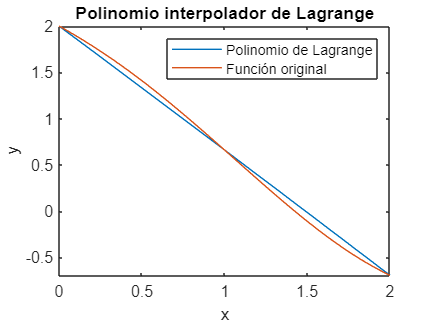

fplot(p2, [0 2])
hold on
fplot(f(x),[0 2])
hold off

% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomio interpolador de Lagrange')
legend("Polinomio de Lagrange","Función original")

**TERCER SOPORTE: S3={x0=0, x1=2/3 ,x2=4/3,x3=2}**

Calculamos el nuevo soporte añadiendo una variable más:

%Calculemos la distancia (constante) que habrá entre los nuevos puntos del
%soporte
hsym = sym((b-a)/n)

$$hsym = \frac{b}{3}-\frac{a}{3}$$

%Sustituimos los valores de a, b y n para nuestro ejemplo:
h = subs(hsym,[b,a,n],[2,0,3])

$$h = \frac{2}{3}$$


%Por tanto, el nuevo soporte será el siguiente:
v3=sym([0,2/3,4/3,2])

$$v3 = \left(\begin{array}{cccc} 0 & \frac{2}{3} & \frac{4}{3} & 2 \end{array}\right)$$

1) Programamos la expresión de los polinomios de base de Lagrange:

%Limpiamos las variables del entorno
clear
%Declaración de variables simbólicas que se utilizarán
syms x L xk xj fi a b
syms x1 x2 x3 x4

%Programamos la expresión simbólica de los polinomios de base de Lagrange:
v=sym([x1,x2,x3,x4])

$$v = \left(\begin{array}{cccc} x_{1} & x_{2} & x_{3} & x_{4} \end{array}\right)$$

n=length(v)

n = 4

L=sym(linspace(1,1,n))

$$L = \left(\begin{array}{cccc} 1 & 1 & 1 & 1 \end{array}\right)$$

for i=1:n %For que crea los Li
    for j=1:n %For del productorio de cada Li
        if (i~=j)
            Li=(x-xj)/(xk-xj)
            prod=subs(Li,{xk,xj},{v(i),v(j)})
            L(i)=L(i)*prod   
        end
    end
end

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{2}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{cccc} \frac{x-x_{2}}{x_{1}-x_{2}} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{1}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{x-x_{1}}{x_{1}-x_{2}} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{2}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & -\frac{x-x_{1}}{x_{1}-x_{3}} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{3}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)} & -\frac{x-x_{1}}{x_{1}-x_{4}} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{3}}{x_{3}-x_{4}}$$

$$L = \left(\begin{array}{cccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)} \end{array}\right)$$

Sustituimos los valores en la expresión de los polinomios de base de Lagrange:

v3=sym([0,2/3,4/3,2])

$$v3 = \left(\begin{array}{cccc} 0 & \frac{2}{3} & \frac{4}{3} & 2 \end{array}\right)$$

n = length(v3)

n = 4


LE = sym(zeros(1,n))

$$LE = \left(\begin{array}{cccc} 0 & 0 & 0 & 0 \end{array}\right)$$


c1 = 1:n

c1 =      1     2     3     4


for i=1:n
    prod1 = 1
    k1 = c1
    k1(i) = []
    for j1=k1
        prod1 = prod1*(x-v3(j1))/(v3(i)-v3(j1))
    end
    LE(i) = prod1
end

prod1 = 1

k1 =      1     2     3     4


k1 =      2     3     4


$$prod1 = 1-\frac{3\,x}{2}$$

$$prod1 = \frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-\frac{4}{3}\right)}{4}$$

$$prod1 = -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{8}$$

$$LE = \left(\begin{array}{cccc} -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{8} & 0 & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4


k1 =      1     3     4


$$prod1 = \frac{3\,x}{2}$$

$$prod1 = -\frac{9\,x\,\left(x-\frac{4}{3}\right)}{4}$$

$$prod1 = \frac{27\,x\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16}$$

$$LE = \left(\begin{array}{cccc} -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{8} & \frac{27\,x\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16} & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4


k1 =      1     2     4


$$prod1 = \frac{3\,x}{4}$$

$$prod1 = \frac{9\,x\,\left(x-\frac{2}{3}\right)}{8}$$

$$prod1 = -\frac{27\,x\,\left(x-2\right)\,\left(x-\frac{2}{3}\right)}{16}$$

$$LE = \left(\begin{array}{cccc} -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{8} & \frac{27\,x\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16} & -\frac{27\,x\,\left(x-2\right)\,\left(x-\frac{2}{3}\right)}{16} & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4


k1 =      1     2     3


$$prod1 = \frac{x}{2}$$

$$prod1 = \frac{3\,x\,\left(x-\frac{2}{3}\right)}{8}$$

$$prod1 = \frac{9\,x\,\left(x-\frac{2}{3}\right)\,\left(x-\frac{4}{3}\right)}{16}$$

$$LE = \left(\begin{array}{cccc} -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{8} & \frac{27\,x\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16} & -\frac{27\,x\,\left(x-2\right)\,\left(x-\frac{2}{3}\right)}{16} & \frac{9\,x\,\left(x-\frac{2}{3}\right)\,\left(x-\frac{4}{3}\right)}{16} \end{array}\right)$$

Representamos gráficamente estos polinomios de base de Lagrange:

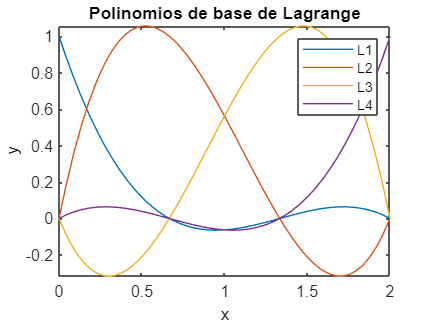

fplot(LE,[0 2])
 
% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomios de base de Lagrange')
legend("L1","L2","L3","L4")

2) Programamos la expresión del polinomio interpolador de Lagrange:

syms f1 f2 f3 f4
fun=[f1,f2,f3,f4]

$$fun = \left(\begin{array}{cccc} f_{1} & f_{2} & f_{3} & f_{4} \end{array}\right)$$


syms L1 L2 L3 L4
l=sym([L1,L2,L3,L4])

$$l = \left(\begin{array}{cccc} L_{1} & L_{2} & L_{3} & L_{4} \end{array}\right)$$

pn=0

pn = 0

for i=1:n
    pI=fi*Li
    val=subs(pI,{fi,Li},{fun(i),l(i)})
    pn=pn+val
end

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{1}\,f_{1}$$

$$pn = L_{1}\,f_{1}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{2}\,f_{2}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{3}\,f_{3}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{4}\,f_{4}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}+L_{4}\,f_{4}$$

Sustituimos los valores para obtener el polinomio interpolador de Lagrange:

%Definimos nuestra función (la usaremos en todos los soportes)
f(x) = exp(-x)+cos(4*x/pi)

$$f(x) = {\mathrm{e}}^{-x}+\cos\left(\frac{4\,x}{\pi }\right)$$


sum = 0

sum = 0

for i=1:n
    sum = sum + LE(i)*f(v3(i))
end

$$sum = -\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{4}$$

$$sum = \frac{27\,x\,\left({\mathrm{e}}^{-\frac{2}{3}}+\cos\left(\frac{8}{3\,\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16}-\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{4}$$

$$sum = \frac{27\,x\,\left({\mathrm{e}}^{-\frac{2}{3}}+\cos\left(\frac{8}{3\,\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16}-\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{4}-\frac{27\,x\,\left({\mathrm{e}}^{-\frac{4}{3}}+\cos\left(\frac{16}{3\,\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{2}{3}\right)}{16}$$

$$sum = \frac{9\,x\,\left({\mathrm{e}}^{-2}+\cos\left(\frac{8}{\pi }\right)\right)\,\left(x-\frac{2}{3}\right)\,\left(x-\frac{4}{3}\right)}{16}-\frac{3\,\left(\frac{3\,x}{2}-1\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{4}+\frac{27\,x\,\left({\mathrm{e}}^{-\frac{2}{3}}+\cos\left(\frac{8}{3\,\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{4}{3}\right)}{16}-\frac{27\,x\,\left({\mathrm{e}}^{-\frac{4}{3}}+\cos\left(\frac{16}{3\,\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{2}{3}\right)}{16}$$


digits(4)
numSum = vpa(sum)

$$numSum = 1.982\,x\,\left(x-2.0\right)\,\left(x-1.333\right)-0.2313\,x\,\left(x-2.0\right)\,\left(x-0.6667\right)-0.3897\,x\,\left(x-0.6667\right)\,\left(x-1.333\right)-0.75\,\left(x-2.0\right)\,\left(x-1.333\right)\,\left(1.5\,x-1.0\right)$$

p3 = expand(numSum)

$$p3 = 0.2356\,x^{3}-0.7091\,x^{2}-0.8705\,x+2.0$$

Representamos gráficamente el polinomio interpolador de Lagrange junto con la función original:

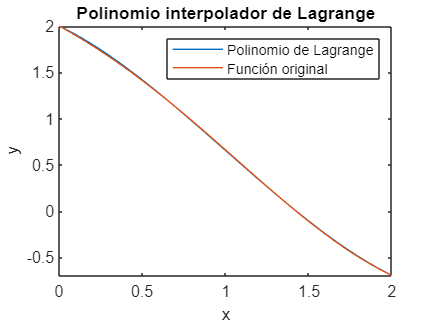

fplot(p3, [0 2])
hold on
fplot(f(x),[0 2])
hold off

% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomio interpolador de Lagrange')
legend("Polinomio de Lagrange","Función original")

**CUARTO SOPORTE: S4={x0=0, x1=1/2,x2=1,x3=3/2,x4=2}**

Calculamos el nuevo soporte añadiendo una variable más:

%Calculemos la distancia (constante) que habrá entre los nuevos puntos del
%soporte
hsym = sym((b-a)/n)

$$hsym = \frac{b}{4}-\frac{a}{4}$$

%Sustituimos los valores de a, b y n para nuestro ejemplo:
h = subs(hsym,[b,a,n],[2,0,4])

$$h = \frac{1}{2}$$


%Por tanto, el nuevo soporte será el siguiente:
v4=sym([0,1/2,1,3/2,2])

$$v4 = \left(\begin{array}{ccccc} 0 & \frac{1}{2} & 1 & \frac{3}{2} & 2 \end{array}\right)$$

1) Programamos la expresión de los polinomios de base de Lagrange:

%Limpiamos las variables del entorno
clear
%Declaración de variables simbólicas que se utilizarán
syms x L xk xj fi a b
syms x1 x2 x3 x4 x5

%Programamos la expresión simbólica de los polinomios de base de Lagrange:
v=sym([x1,x2,x3,x4,x5])

$$v = \left(\begin{array}{ccccc} x_{1} & x_{2} & x_{3} & x_{4} & x_{5} \end{array}\right)$$

n=length(v)

n = 5

L=sym(linspace(1,1,n))

$$L = \left(\begin{array}{ccccc} 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

for i=1:n %For que crea los Li
    for j=1:n %For del productorio de cada Li
        if (i~=j)
            Li=(x-xj)/(xk-xj)
            prod=subs(Li,{xk,xj},{v(i),v(j)})
            L(i)=L(i)*prod   
        end
    end
end

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{2}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{ccccc} \frac{x-x_{2}}{x_{1}-x_{2}} & 1 & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)} & 1 & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{1}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)} & 1 & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{5}}{x_{1}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & 1 & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{2}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{x-x_{1}}{x_{1}-x_{2}} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{3}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{2}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{5}}{x_{2}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & 1 & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{3}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & -\frac{x-x_{1}}{x_{1}-x_{3}} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{3}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{4}}{x_{3}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{5}}{x_{3}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & 1 & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{x-x_{1}}{x_{1}-x_{4}} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{3}}{x_{3}-x_{4}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = \frac{x-x_{5}}{x_{4}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{4}-x_{5}\right)} & 1 \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{1}}{x_{1}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{4}-x_{5}\right)} & -\frac{x-x_{1}}{x_{1}-x_{5}} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{2}}{x_{2}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{4}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)}{\left(x_{1}-x_{5}\right)\,\left(x_{2}-x_{5}\right)} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{3}}{x_{3}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{4}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)}{\left(x_{1}-x_{5}\right)\,\left(x_{2}-x_{5}\right)\,\left(x_{3}-x_{5}\right)} \end{array}\right)$$

$$Li = -\frac{x-\mathrm{xj}}{\mathrm{xj}-\mathrm{xk}}$$

$$prod = -\frac{x-x_{4}}{x_{4}-x_{5}}$$

$$L = \left(\begin{array}{ccccc} \frac{\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{1}-x_{3}\right)\,\left(x_{1}-x_{4}\right)\,\left(x_{1}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{2}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{2}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{4}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{3}\right)\,\left(x_{2}-x_{3}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{3}-x_{5}\right)} & -\frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{5}\right)}{\left(x_{1}-x_{4}\right)\,\left(x_{2}-x_{4}\right)\,\left(x_{3}-x_{4}\right)\,\left(x_{4}-x_{5}\right)} & \frac{\left(x-x_{1}\right)\,\left(x-x_{2}\right)\,\left(x-x_{3}\right)\,\left(x-x_{4}\right)}{\left(x_{1}-x_{5}\right)\,\left(x_{2}-x_{5}\right)\,\left(x_{3}-x_{5}\right)\,\left(x_{4}-x_{5}\right)} \end{array}\right)$$

Sustituimos los valores en la expresión de los polinomios de base de Lagrange:

v4=sym([0,1/2,1,3/2,2])

$$v4 = \left(\begin{array}{ccccc} 0 & \frac{1}{2} & 1 & \frac{3}{2} & 2 \end{array}\right)$$

n = length(v4)

n = 5


LE = sym(zeros(1,n))

$$LE = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


c1 = 1:n

c1 =      1     2     3     4     5


for i=1:n
    prod1 = 1
    k1 = c1
    k1(i) = []
    for j1=k1
        prod1 = prod1*(x-v4(j1))/(v4(i)-v4(j1))
    end
    LE(i) = prod1
end

prod1 = 1

k1 =      1     2     3     4     5


k1 =      2     3     4     5


$$prod1 = 1-2\,x$$

$$prod1 = \left(2\,x-1\right)\,\left(x-1\right)$$

$$prod1 = -\frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$prod1 = \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$LE = \left(\begin{array}{ccccc} \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & 0 & 0 & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4     5


k1 =      1     3     4     5


$$prod1 = 2\,x$$

$$prod1 = -4\,x\,\left(x-1\right)$$

$$prod1 = 4\,x\,\left(x-1\right)\,\left(x-\frac{3}{2}\right)$$

$$prod1 = -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$LE = \left(\begin{array}{ccccc} \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & 0 & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4     5


k1 =      1     2     4     5


$$prod1 = x$$

$$prod1 = 2\,x\,\left(x-\frac{1}{2}\right)$$

$$prod1 = -4\,x\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)$$

$$prod1 = 4\,x\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)$$

$$LE = \left(\begin{array}{ccccc} \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & 4\,x\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right) & 0 & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4     5


k1 =      1     2     3     5


$$prod1 = \frac{2\,x}{3}$$

$$prod1 = \frac{2\,x\,\left(x-\frac{1}{2}\right)}{3}$$

$$prod1 = \frac{4\,x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)}{3}$$

$$prod1 = -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)}{3}$$

$$LE = \left(\begin{array}{ccccc} \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & 4\,x\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right) & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)}{3} & 0 \end{array}\right)$$

prod1 = 1

k1 =      1     2     3     4     5


k1 =      1     2     3     4


$$prod1 = \frac{x}{2}$$

$$prod1 = \frac{x\,\left(x-\frac{1}{2}\right)}{3}$$

$$prod1 = \frac{x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)}{3}$$

$$prod1 = \frac{2\,x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$LE = \left(\begin{array}{ccccc} \frac{\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3} & 4\,x\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right) & -\frac{8\,x\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)}{3} & \frac{2\,x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)}{3} \end{array}\right)$$

Representamos gráficamente estos polinomios de base de Lagrange:

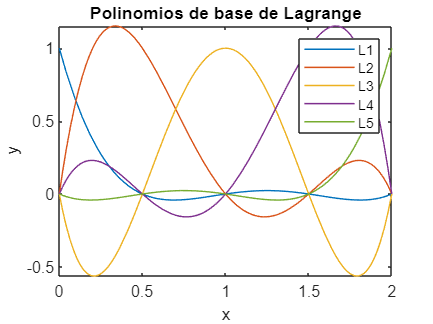

fplot(LE,[0 2])
 
% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomios de base de Lagrange')
legend("L1","L2","L3","L4","L5")

2) Programamos la expresión del polinomio interpolador de Lagrange:

syms f1 f2 f3 f4 f5
fun=[f1,f2,f3,f4,f5]

$$fun = \left(\begin{array}{ccccc} f_{1} & f_{2} & f_{3} & f_{4} & f_{5} \end{array}\right)$$


syms L1 L2 L3 L4 L5
l=sym([L1,L2,L3,L4,L5])

$$l = \left(\begin{array}{ccccc} L_{1} & L_{2} & L_{3} & L_{4} & L_{5} \end{array}\right)$$

pn=0

pn = 0

for i=1:n
    pI=fi*Li
    val=subs(pI,{fi,Li},{fun(i),l(i)})
    pn=pn+val
end

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{1}\,f_{1}$$

$$pn = L_{1}\,f_{1}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{2}\,f_{2}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{3}\,f_{3}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{4}\,f_{4}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}+L_{4}\,f_{4}$$

$$pI = -\frac{\mathrm{fi}\,\left(x-\mathrm{xj}\right)}{\mathrm{xj}-\mathrm{xk}}$$

$$val = L_{5}\,f_{5}$$

$$pn = L_{1}\,f_{1}+L_{2}\,f_{2}+L_{3}\,f_{3}+L_{4}\,f_{4}+L_{5}\,f_{5}$$

Sustituimos los valores para obtener el polinomio interpolador de Lagrange:

%Definimos nuestra función (la usaremos en todos los soportes)
f(x) = exp(-x)+cos(4*x/pi)

$$f(x) = {\mathrm{e}}^{-x}+\cos\left(\frac{4\,x}{\pi }\right)$$


sum = 0

sum = 0

for i=1:n
    sum = sum + LE(i)*f(v4(i))
end

$$sum = \frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$sum = \frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{1}{2}}+\cos\left(\frac{2}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}$$

$$sum = \frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{1}{2}}+\cos\left(\frac{2}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}+4\,x\,\left({\mathrm{e}}^{-1}+\cos\left(\frac{4}{\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)$$

$$sum = \frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{1}{2}}+\cos\left(\frac{2}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}+4\,x\,\left({\mathrm{e}}^{-1}+\cos\left(\frac{4}{\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{3}{2}}+\cos\left(\frac{6}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)}{3}$$

$$sum = \frac{2\,\left(2\,x-1\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{1}{2}}+\cos\left(\frac{2}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{3}{2}\right)}{3}+4\,x\,\left({\mathrm{e}}^{-1}+\cos\left(\frac{4}{\pi }\right)\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)-\frac{8\,x\,\left({\mathrm{e}}^{-\frac{3}{2}}+\cos\left(\frac{6}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-2\right)\,\left(x-\frac{1}{2}\right)}{3}+\frac{2\,x\,\left({\mathrm{e}}^{-2}+\cos\left(\frac{8}{\pi }\right)\right)\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{3}{2}\right)}{3}$$


digits(4)
numSum = vpa(sum)

$$numSum = 0.2919\,x\,\left(x-0.5\right)\,\left(x-1.0\right)\,\left(x-2.0\right)-0.4618\,x\,\left(x-0.5\right)\,\left(x-1.0\right)\,\left(x-1.5\right)+2.644\,x\,\left(x-0.5\right)\,\left(x-2.0\right)\,\left(x-1.5\right)-3.762\,x\,\left(x-1.0\right)\,\left(x-2.0\right)\,\left(x-1.5\right)+0.6667\,\left(x-1.0\right)\,\left(x-2.0\right)\,\left(x-1.5\right)\,\left(2.0\,x-1.0\right)$$

p4 = expand(numSum)

$$p4 = 0.04598\,x^{4}+0.04773\,x^{3}-0.4725\,x^{2}-0.9602\,x+2.0$$

Representamos gráficamente el polinomio interpolador de Lagrange junto con la función original:

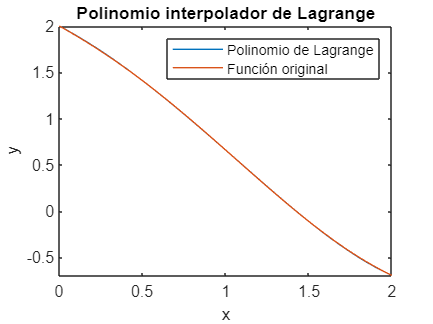

fplot(p4, [0 2])
hold on
fplot(f(x),[0 2])
hold off

% Add ylabel, title, and legend
xlabel('x')
ylabel('y')
title('Polinomio interpolador de Lagrange')
legend("Polinomio de Lagrange","Función original")